**Project - Equations of motion matlab script**

**Initialize**

syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist bc bp
mc=0.9+0.1; 
mp=0.08887;
l = 0.175;
l= 0.36022/2;
g = 9.82;
bc = 8.5;
bp = 0.0012;

**Without Disturbance linear**

 %E = [(mc+mp)*ddx == (mp*l*ddth)/2 + F - bc*dx, (mp*l^2*ddth)/4 == (mp*ddx*l)/2 + (mp*g*l*th)/2 - bp*dth];
 %E = [(mc+mp)*ddx - mp*l*ddth == F - bc*dx, mp*l^2*ddth + mp*ddx*l - mp*g*l*th == -Fdist - bp*dth];
 E = [(mc+mp)*ddx - mp*l*ddth == F - bc*dx, mp*l^2*ddth + mp*ddx*l - mp*g*l*th == - bp*dth];
 S0 = solve(E,ddx,ddth);
 S0.ddx

$$ans = \frac{73679848216512742220103680000000000\,F}{86775704438515717499046783607616399}-\frac{15217868822687657930684104704000000\,\mathrm{dth}}{2690046837593987242470450291836108369}-\frac{626278709840358308870881280000000000\,\mathrm{dx}}{86775704438515717499046783607616399}+\frac{127572497635268660438856906144931640625\,\mathrm{th}}{172162997606015183518108818677510935616}$$

 temp = -((bc*l)/(l*(mc+2*mp)))*dx   + ((g*l*mp)/(l*(mc+2*mp)))*th    - ((bp)/(l*(mc+2*mp)))*dth   + (l/(l*(mc+2*mp)))*F %- ((1)/(l*(mc+2*mp)))*Fdist

$$temp = \frac{50000\,F}{58887}-\frac{1630548581419419\,\mathrm{dth}}{288230376151711744}-\frac{8125859025049929\,\mathrm{dx}}{1125899906842624}+\frac{6674319810900479\,\mathrm{th}}{9007199254740992}$$

 simplify(temp)

$$ans = \frac{50000\,F}{58887}-\frac{1630548581419419\,\mathrm{dth}}{288230376151711744}-\frac{8125859025049929\,\mathrm{dx}}{1125899906842624}+\frac{6674319810900479\,\mathrm{th}}{9007199254740992}$$

 
 S0.ddth

$$ans = \frac{3477201209485083410125205190352044032\,\mathrm{dx}}{86775704438515717499046783607616399}-\frac{33394517154931745665459421184000000\,\mathrm{dth}}{86775704438515717499046783607616399}-\frac{409082495233539224720612375335534592\,F}{86775704438515717499046783607616399}+\frac{4374197787664148640055487314687500000\,\mathrm{th}}{86775704438515717499046783607616399}$$

 temp = ((bc*l*mp)/(l^2*mp*(mc+2*mp)))*dx   + ((g*l*mp*(mp+mc))/(l^2*mp*(mc+2*mp)))*th    - ((bp*(mc+mp))/(l^2*mp*(mc+2*mp)))*dth    - (l*mp/(l^2*mp*(mc+2*mp)))*F %- ((mc-mp)/(l^2*mp*(mc+2*mp)))*Fdist

$$temp = \frac{1409877822068793\,\mathrm{dx}}{35184372088832}-\frac{6932610273269743\,\mathrm{dth}}{18014398509481984}-\frac{2653887665070669\,F}{562949953421312}+\frac{7094308414879801\,\mathrm{th}}{140737488355328}$$

 simplify(temp)

$$ans = \frac{1409877822068793\,\mathrm{dx}}{35184372088832}-\frac{6932610273269743\,\mathrm{dth}}{18014398509481984}-\frac{2653887665070669\,F}{562949953421312}+\frac{7094308414879801\,\mathrm{th}}{140737488355328}$$

**With Disturbance linaer**

% E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
% S1 = solve(E1,ddx,ddth);
% S1.ddx;
% S1.ddth;

**Nonlinear**

% E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
% S2 = solve(E2, ddx, ddth);
% S2.ddx;
% S2.ddth;

**Fpend and Fcart are b * x/th**

% E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
% S3 = solve(E3, ddx, ddth);
% S3.ddx;
% S3.ddth;

**State Space Model**

C = [0 1 0 0;
     1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 0 1 0;
     0 0 0 1;
     0 ((g*l*mp)/(l*(mc+2*mp))) -((bc*l)/(l*(mc+2*mp))) -((bp)/(l*(mc+2*mp)));
     0 ((g*l*mp*(mp+mc))/(l^2*mp*(mc+2*mp))) ((bc*l*mp)/(l^2*mp*(mc+2*mp))) -((bp*(mc+mp))/(l^2*mp*(mc+2*mp)))]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    0.7410   -7.2172   -0.0057
         0   50.4081   40.0711   -0.3848


 
 
 %*dx   + *th    -*dth  - *Fdist   + *F
 %*dx   + *th    -*dth   - *Fdist   -*F
 
  
B = [0 0;
     0 0;
     -((1)/(l*(mc+2*mp))) (l/(l*(mc+2*mp)));
     -((mc-mp)/(l^2*mp*(mc+2*mp))) -(l*mp/(l^2*mp*(mc+2*mp)))]

B =          0         0
         0         0
   -4.7143    0.8491
 -268.3491   -4.7143



 %u = [F; 0];
 
system = ss(A,B,C,0)

system =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      0.741     -7.217  -0.005657
   x4          0      50.41      40.07    -0.3848
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3  -4.714  0.8491
   x4  -268.3  -4.714
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Observability and Controlability**

observability = obsv(system)

observability =          0    1.0000         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0         0    1.0000         0
         0   50.4081   40.0711   -0.3848
         0    0.7410   -7.2172   -0.0057
         0   10.2937 -304.6228   50.3295
         0   -5.6331   51.8615    0.7840


%rank(observability); % Full rank
symObs = [ C     ; 
           C*A   ;
           C*A^2 ;
           C*A^3 ]

symObs =          0    1.0000         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0         0    1.0000         0
         0   50.4081   40.0711   -0.3848
         0    0.7410   -7.2172   -0.0057
         0   10.2937 -304.6228   50.3295
         0   -5.6331   51.8615    0.7840


ObsRank = rank(symObs)

ObsRank = 4


controlability = ctrb(system)

controlability = 	1.0e+04 *

         0         0   -0.0005    0.0001    0.0036   -0.0006   -0.0455    0.0040
         0         0   -0.0268   -0.0005   -0.0086    0.0036   -1.2070   -0.0496
   -0.0005    0.0001    0.0036   -0.0006   -0.0455    0.0040    0.3288   -0.0262
   -0.0268   -0.0005   -0.0086    0.0036   -1.2070   -0.0496   -1.7899    0.3614


%rank(controlability); % Full rank
symCon = [B, A*B, A^2*B, A^3*B]

symCon = 	1.0e+04 *

         0         0   -0.0005    0.0001    0.0036   -0.0006   -0.0455    0.0040
         0         0   -0.0268   -0.0005   -0.0086    0.0036   -1.2070   -0.0496
   -0.0005    0.0001    0.0036   -0.0006   -0.0455    0.0040    0.3288   -0.0262
   -0.0268   -0.0005   -0.0086    0.0036   -1.2070   -0.0496   -1.7899    0.3614


ConRank = rank(symCon)

ConRank = 4

## **Pole Placement Method**

**Extended Matrices**

A_e = [A zeros([4 2]);
       C zeros([2 2])]

A_e =          0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0    0.7410   -7.2172   -0.0057         0         0
         0   50.4081   40.0711   -0.3848         0         0
         0    1.0000         0         0         0         0
    1.0000         0         0         0         0         0


B_e = [B;
       zeros([2 2])];
C_e = [C zeros([2 2])];

**Pole Placement - settling of +/-3% in 1 second.**

ts = 1;
alpha = 3;
sigma = -log10((alpha/100)/100)/ts

sigma = 3.5229


poles = -[sigma+1i sigma-1i sigma*5+1i sigma*5-1i sigma*6+1i sigma*6-1i]

poles =   -3.5229 - 1.0000i  -3.5229 + 1.0000i -17.6144 - 1.0000i -17.6144 + 1.0000i -21.1373 - 1.0000i -21.1373 + 1.0000i


% Tried to plot with poles on the real axis. This did not work either.
% poles = -[sigma sigma*5 sigma*7 sigma*12 sigma*18 sigma*22]

Fe = -place(A_e, B_e, poles);
F = Fe(1:2, 1:4)

F =    14.8177   10.0494    0.9307    0.3601
 -875.7067 -514.3470  -45.2195  -13.2527


Fi = Fe(1:2, 5:6)

Fi = 	1.0e+03 *

    0.0806    0.0757
   -4.8726   -4.6693



% feedback = A_e + B_e * Fe;
% eigMat = eig(A_e + B_e * Fe);

## 3. Observer design

Pole selection

OBS = [-sigma*5.1+1i -sigma*5.1-1i -sigma*6.1+1i -sigma*6.1-1i]

OBS =  -17.9667 + 1.0000i -17.9667 - 1.0000i -21.4896 + 1.0000i -21.4896 - 1.0000i


%OBS = [OBS1-0.1 OBS1-0.2 OBS1-0.3 OBS1-0.4];

Observer design    

L = -place(system.A', system.C', OBS).'

L = 	1.0e+03 *

    0.0001   -0.0318
   -0.0395   -0.0358
   -0.0022   -0.1391
   -0.4362   -1.1392


Anti windup

MP = [-sigma*5.5+1i -sigma*5.5-1i -sigma*6.5+1i -sigma*6.5-1i]

MP =  -19.3758 + 1.0000i -19.3758 - 1.0000i -22.8987 + 1.0000i -22.8987 - 1.0000i


%MP = [-15 -20 -25 -30]
M = -place((A + L * C)', F', MP).'

M =    -0.2401   -0.0044
   -4.4310   -0.0924
   -2.9064   -0.0521
  -98.7408   -2.0345


## **Transfer functions and PID controller **

## **Not used yet.**

SA = inv(S-A)

SA =
 
  From input 1 to output...
       1
   1:  -
       s
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
                     0.741 s + 1.302e-13
   1:  ------------------------------------------------
       s^4 + 7.602 s^3 - 47.4 s^2 - 393.5 s - 3.951e-12
 
            s^2 + 7.602 s + 3.004
   2:  --------------------------------
       s^3 + 7.602 s^2 - 47.4 s - 393.5
 
              0.741 s - 1.52e-13
   3:  --------------------------------
       s^3 + 7.602 s^2 - 47.4 s - 393.5
 
               50.41 s + 393.5
   4:  --------------------------------
       s^3 + 7.602 s^2 - 47.4 s - 393.5
 
  From input 3 to output...
                    s^2 + 0.3848 s - 50.41
   1:  ------------------------------------------------
       s^4 + 7.602 s^3 - 47.4 s^2 - 393.5 s + 2.617e-12
 
                    40.07
   2:  --------------------------------
       s^3 + 7.602 s^2 - 47.4 s - 393.5
 
            s^2 + 0.3848 s - 50.41
   3:  --------------------------------
       s

% G8 = C*SA*B

[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1)

Gnum = 	1.0e+03 *

         0         0   -0.2683   -2.1256   -0.0000
         0         0   -0.0047   -0.0003    0.0388


Gden =     1.0000    7.6020  -47.4040 -393.4986         0


SS2TF1 = Gnum(1,:);
SS2TF2 = Gnum(2,:);
 
G1 =tf(SS2TF1, Gden)

G1 =
 
    -268.3 s^2 - 2126 s - 1.888e-12
  ------------------------------------
  s^4 + 7.602 s^3 - 47.4 s^2 - 393.5 s
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
     -4.714 s^2 - 0.2961 s + 38.79
  ------------------------------------
  s^4 + 7.602 s^3 - 47.4 s^2 - 393.5 s
 
Continuous-time transfer function.



**PID**

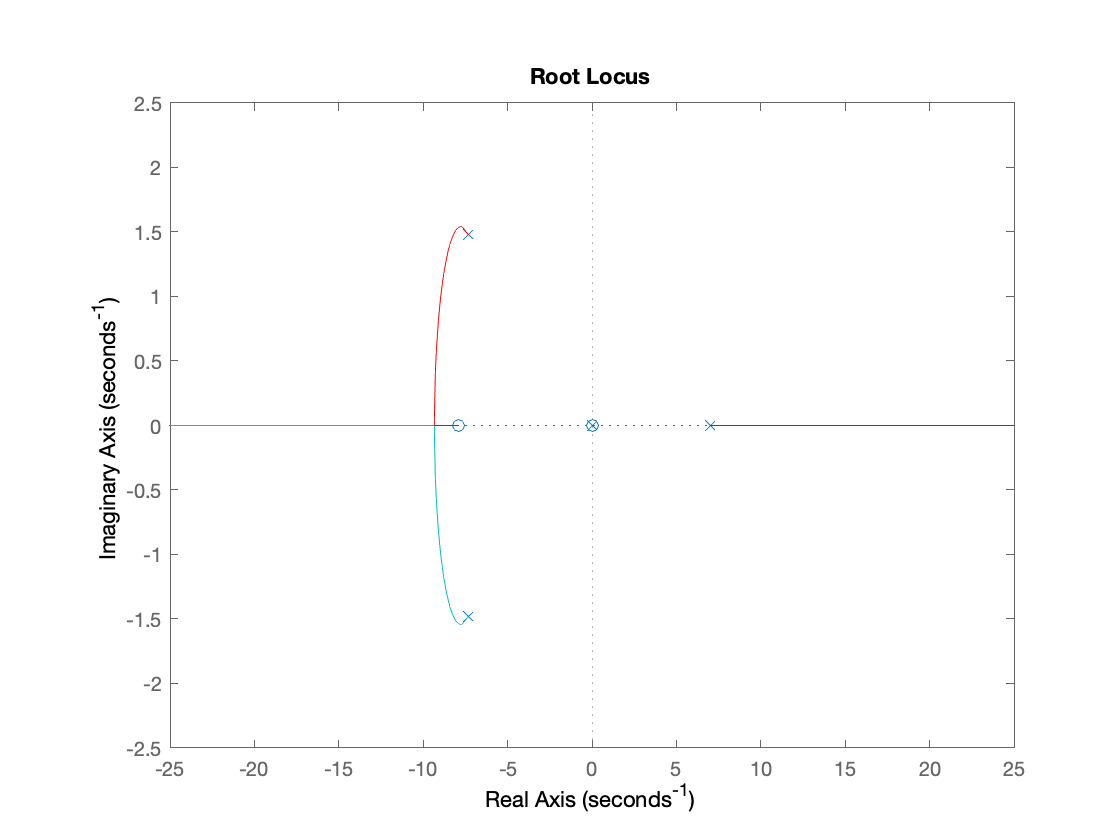

Kp = 50;
Ti = 0.1;
Td = 0.1;

Ks = Kp * (1 + 1 / (Ti * s) + Td * s);
rlocus(G1);

% step(Ks*G2);

% pid(Kp,Ti,Td)


% rlocus(G1);
% rlocus(G2);
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);